# **RS-WISP-08-04: GEO AR&D Trajectory Generation **

WorkerInSpace

Hongseok Kim

2025/07/07

## I. Phase 1: GTO to near-GEO transfer

mu = 398600.4415;
r_p = 6378 + 200;
r_a = 6378 + 36000;
inc = 28;
n = 5;

[inc_vec, ecc_vec, delta_v_y, delta_v_z] = GTO_to_GEO_trajectory(r_a, r_p, inc, n)

inc_vec =    28.0000
   18.9772
   12.2132
    7.0863
    3.1250
         0


ecc_vec =     0.7313
    0.6415
    0.5236
    0.3773
    0.2028
         0


delta_v_y = 0.3326

delta_v_z = -0.1493

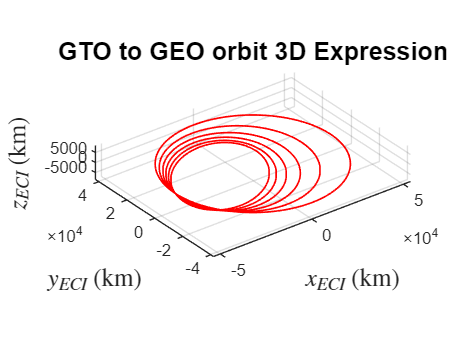



%% Define Initial Orbit Parameter

figure;
hold on


for i = 1:n+1 

ecc = ecc_vec(i);
SMA = r_a / (1+ecc); 
inc = inc_vec(i);
RAAN = 0;
AOP = 0;
theta = 0;
orbit_period = 2*pi* sqrt(SMA^3/mu);
time_vector = [0:1:orbit_period, orbit_period];
[r0,v0]=kepler2ijk_hs(SMA,ecc,inc,RAAN,AOP,theta);
[t,y] = orbit_propagation(r0,v0,time_vector);
r = y(:,1:3);
v = y(:,4:6);
vel_aps(2) = norm(v(1,:));
plot3(r(:,1),r(:,2),r(:,3),'LineWidth',1,'Color','r')

end
axis('equal')
view(3)
hold off
title('GTO to GEO orbit 3D Expression','FontSize',15,'FontWeight','bold')
xlabel('$x_{ECI}$ (km)', 'Interpreter', 'latex','FontSize',15) 
ylabel('$y_{ECI}$ (km)', 'Interpreter', 'latex','FontSize',15)
zlabel('$z_{ECI}$ (km)', 'Interpreter', 'latex','FontSize',15)
grid on


fprintf('total %4.0f impulse burns',n)

total    5 impulse burns

fprintf('Total Delta v is: in-track %4.4f km/s, cross-track %4.4f km/s',  delta_v_y*n, delta_v_z*n)

Total Delta v is: in-track 1.6631 km/s, cross-track -0.7464 km/s

fprintf('Delta v per burn is: in-track %4.4f km/s, cross-track %4.4f km/s',  delta_v_y, delta_v_z)

Delta v per burn is: in-track 0.3326 km/s, cross-track -0.1493 km/s

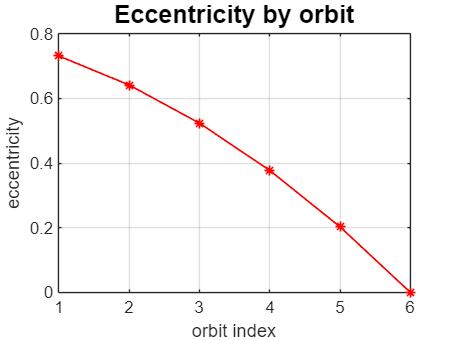


figure;
plot(1:n+1, ecc_vec,'r','LineWidth',1,'Marker','*')
title('Eccentricity by orbit','FontSize',15,'FontWeight','bold')
grid on
xlabel('orbit index')
ylabel('eccentricity')

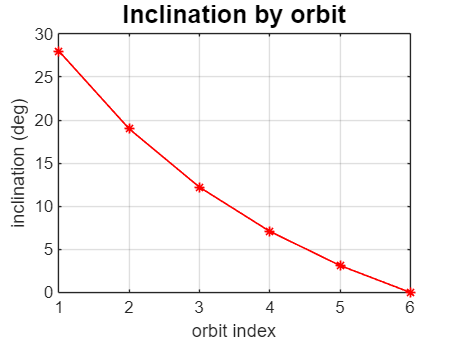



figure;
plot(1:n+1, inc_vec,'r','LineWidth',1,'Marker','*')
title('Inclination by orbit','FontSize',15,'FontWeight','bold')
grid on
xlabel('orbit index')
ylabel('inclination (deg)')




function [inc_vec, ecc_vec, delta_v_y, delta_v_z] = GTO_to_GEO_trajectory(r_a, r_p, i, n)

% Step 1: get initial velocity vector
mu = 398600.4415;
r = r_a;
a = (r_a + r_p)/2;
v = sqrt(mu * (2/r - 1/a));
v_y0 = v * cos(i /180*pi);
v_z0 = v * sin(i /180*pi);

% Step 2: get final velocity vector
v_yn = sqrt(mu/r_a);
v_zn = 0;
delta_v_y = 1/n * (v_yn - v_y0);
delta_v_z = 1/n * (v_zn - v_z0);

% Step 3: get matrix of velocity vector for each revolution
velocity_info_mat = zeros(n+1,2);
for i = 0:n
velocity_info_mat(i+1,1) = v_y0 + i * delta_v_y;
velocity_info_mat(i+1,2) = v_z0 + i * delta_v_z;
end

% Step 4: get matrix of eccentricity and inclination for each revolution
inc_vec = zeros(n+1,1);
ecc_vec = zeros(n+1,1);

for i = 0:n

v_y = velocity_info_mat(i+1,1);
v_z = velocity_info_mat(i+1,2);

ecc = 1-r_a * (v_y^2 + v_z^2)/mu;

sin_i = v_z / sqrt(v_y^2+v_z^2);
cos_i = v_y / sqrt(v_y^2+v_z^2);

    if sin_i >= 0 
        inc = acos(cos_i)/pi*180;
    else
        inc = (acos(cos_i)+pi)/pi*180;
    end

ecc_vec(i+1) = ecc;
inc_vec(i+1) = inc;

end

end

## II. Phase 2: Co-Elliptic Rendezvous with Hohmann Raises

radius_of_chaser = 6378 + 36000 - 100;
radius_of_target = 6378 + 36000;
TA_of_chaser = 30;
TA_of_target = 35;
n = 1;



SMA = radius_of_chaser; 
theta = TA_of_chaser;
inc = 0;
RAAN = 0;
AOP = 0;
ecc = 0;
[r_chaser,v_chaser]=kepler2ijk_hs(SMA,ecc,inc,RAAN,AOP,theta);


SMA = radius_of_target; 
theta = TA_of_target;
inc = 0;
RAAN = 0;
AOP = 0;
ecc = 0;
[r_target,v_target]=kepler2ijk_hs(SMA,ecc,inc,RAAN,AOP,theta);

[delta_v_1_vec, delta_v_2_vec, t_H_vec, t_E_vec] = hohmann_and_co_elliptic(r_chaser, r_target, n)

delta_v_1_vec = 0.0018

delta_v_2_vec = 0.0018

t_H_vec = 4.3333e+04

t_E_vec = 3.1803e+05


r_chaser_eci_info = r_chaser';

r_chaser_eci_info = 1.0e+04 *

    3.6614    2.1139         0


v_chaser_eci_info = v_chaser';

v_chaser_eci_info =    -1.5353    2.6591         0


r_target_eci_info = r_target';

r_target_eci_info = 1.0e+04 *

    3.4714    2.4307         0


v_target_eci_info = v_target';

v_target_eci_info =    -1.7591    2.5123         0



for i = 1:n

t_E = linspace(0,t_E_vec(i));
t_H = linspace(0,t_H_vec(i));
delta_v_1 = delta_v_1_vec(i);
delta_v_2 = delta_v_2_vec(i);

% Co-elliptic transfer
[t,y_c] = orbit_propagation(r_chaser_eci_info(end,:), v_chaser_eci_info(end,:), t_E);
[t,y_t] = orbit_propagation(r_target_eci_info(end,:), v_target_eci_info(end,:), t_E);

y_c
y_t

r_chaser_eci_info = [r_chaser_eci_info;y_c(:,1:3)]
v_chaser_eci_info = [v_chaser_eci_info;y_c(:,4:6)]

r_target_eci_info = [r_target_eci_info;y_t(:,1:3)]
v_target_eci_info = [v_target_eci_info;y_t(:,4:6)]

% Hohmann-transfer

r_c_eci = r_chaser_eci_info(end,:);
v_c_eci = v_chaser_eci_info(end,:);
v_c_eci_updated = v_c_eci / norm(v_c_eci) * (norm(v_c_eci)+delta_v_1);

r_t_eci = r_target_eci_info(end,:);
v_t_eci = v_target_eci_info(end,:);

[t,y_c] = orbit_propagation(r_c_eci, v_c_eci_updated, t_H);
[t,y_t] = orbit_propagation(r_t_eci, v_t_eci, t_H);

r_chaser_eci_info = [r_chaser_eci_info;y_c(:,1:3)];
v_chaser_eci_info = [v_chaser_eci_info;y_c(:,4:6)];

v_chaser_eci_info(end,:) = v_chaser_eci_info(end,:) /  norm(v_chaser_eci_info(end,:)) * (norm(v_chaser_eci_info(end,:)) + delta_v_2);

r_target_eci_info = [r_target_eci_info;y_t(:,1:3)];
v_target_eci_info = [v_target_eci_info;y_t(:,4:6)];

end

y_c = 1.0e+04 *

    3.6614   -0.0002    2.1139    0.0003         0         0
    4.4243   -0.0001    2.0647    0.0002    0.0000   -0.0000
    5.0293   -0.0001    1.9409    0.0002    0.0000   -0.0000
    5.5014   -0.0001    1.7655    0.0001    0.0000   -0.0001
    5.8558   -0.0001    1.5521    0.0001    0.0000   -0.0001
    6.1015   -0.0001    1.3097    0.0001    0.0000   -0.0001
    6.2436   -0.0001    1.0451    0.0000    0.0000   -0.0001
    6.2843   -0.0001    0.7635   -0.0000    0.0000   -0.0001
    6.2229   -0.0000    0.4694   -0.0000    0.0000   -0.0001
    6.0559   -0.0000    0.1675   -0.0001    0.0000   -0.0001


y_t = 1.0e+04 *

    3.4714   -0.0002    2.4307    0.0003         0         0
    4.1910   -0.0002    2.3736    0.0002    0.0000   -0.0000
    4.7552   -0.0002    2.2276    0.0002    0.0000   -0.0001
    5.1836   -0.0001    2.0175    0.0001    0.0000   -0.0001
    5.4877   -0.0001    1.7588    0.0001    0.0000   -0.0001
    5.6735   -0.0001    1.4622    0.0000    0.0000   -0.0001
    5.7430   -0.0001    1.1355    0.0000    0.0000   -0.0001
    5.6944   -0.0001    0.7855   -0.0000    0.0000   -0.0001
    5.5221   -0.0000    0.4185   -0.0001    0.0000   -0.0001
    5.2154   -0.0000    0.0416   -0.0001    0.0000   -0.0001


r_chaser_eci_info = 1.0e+04 *

    3.6614    2.1139         0
    3.6614   -0.0002    2.1139
    4.4243   -0.0001    2.0647
    5.0293   -0.0001    1.9409
    5.5014   -0.0001    1.7655
    5.8558   -0.0001    1.5521
    6.1015   -0.0001    1.3097
    6.2436   -0.0001    1.0451
    6.2843   -0.0001    0.7635
    6.2229   -0.0000    0.4694


v_chaser_eci_info =    -1.5353    2.6591         0
    2.6591         0         0
    2.1124    0.0000   -0.2847
    1.6667    0.0000   -0.4745
    1.2804    0.0000   -0.6109
    0.9304    0.0001   -0.7133
    0.6019    0.0001   -0.7921
    0.2843    0.0001   -0.8527
   -0.0312    0.0001   -0.8983
   -0.3530    0.0001   -0.9299


r_target_eci_info = 1.0e+04 *

    3.4714    2.4307         0
    3.4714   -0.0002    2.4307
    4.1910   -0.0002    2.3736
    4.7552   -0.0002    2.2276
    5.1836   -0.0001    2.0175
    5.4877   -0.0001    1.7588
    5.6735   -0.0001    1.4622
    5.7430   -0.0001    1.1355
    5.6944   -0.0001    0.7855
    5.5221   -0.0000    0.4185


v_target_eci_info =    -1.7591    2.5123         0
    2.5123         0         0
    1.9851    0.0000   -0.3328
    1.5373    0.0000   -0.5640
    1.1358    0.0001   -0.7360
    0.7605    0.0001   -0.8690
    0.3973    0.0001   -0.9739
    0.0343    0.0001   -1.0565
   -0.3398    0.0001   -1.1192
   -0.7384    0.0001   -1.1618


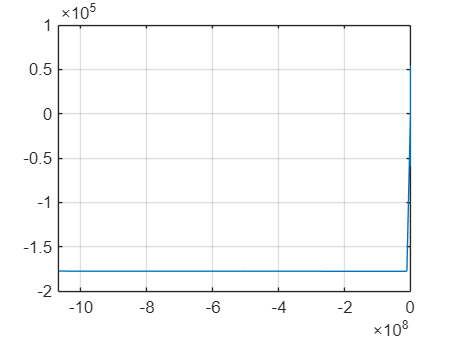



r_lvlh_info = zeros(length(r_chaser_eci_info(:,1)),3);
v_lvlh_info = zeros(length(r_chaser_eci_info(:,1)),3);

for time_index = 1:length(r_chaser_eci_info(:,1))

    r_t_eci_current = r_target_eci_info(time_index,:)';
    v_t_eci_current = v_target_eci_info(time_index,:)';
    r_c_eci_current = r_chaser_eci_info(time_index,:)';
    v_c_eci_current = v_chaser_eci_info(time_index,:)';
    n = sqrt(mu/(norm(r_t_eci_current)^3));

    [r_lvlh_current, v_lvlh_current] = eci2lvlh(r_t_eci_current, v_t_eci_current, r_c_eci_current, v_c_eci_current, n);
    r_lvlh_info(time_index,:) = r_lvlh_current';
    v_lvlh_info(time_index,:) = v_lvlh_current';    


end
figure
plot(r_lvlh_info(:,1),r_lvlh_info(:,2))
grid on





function [delta_v_1_vec, delta_v_2_vec, t_H_vec, t_E_vec] = hohmann_and_co_elliptic(r_chaser, r_target, n)
mu = 398600.4415;
% Step 1: get delta_theta

     x_c_eci = r_chaser(1);
     y_c_eci = r_chaser(2);
     x_t_eci = r_target(1);
     y_t_eci = r_target(2);
    
    if y_c_eci >=0
        theta_c = acos(x_c_eci / sqrt(x_c_eci^2+y_c_eci^2));
    else
        theta_c = acos(x_c_eci / sqrt(x_c_eci^2+y_c_eci^2))+pi;
    end
    
    if y_t_eci >=0
        theta_t = acos(x_t_eci / sqrt(x_t_eci^2+y_t_eci^2));
    else
        theta_t = acos(x_t_eci / sqrt(x_t_eci^2+y_t_eci^2))+pi;
    end
    
    delta_theta = theta_t - theta_c;
    delta_theta_i = - delta_theta/n;
% Step 2: get chaser radius information

    r_0 = norm(r_chaser);
    r_n = norm(r_target);
    delta_r = (r_n - r_0)/n;
    
    radius_vec = zeros(n+1,1);
    
    for i = 0:n
        radius_vec(i+1) = r_0 + i *delta_r;
    end

% Step 3: Hohmann transfer design

delta_v_1_vec = zeros(n,1);
delta_v_2_vec = zeros(n,1);
t_H_vec = zeros(n,1);
t_E_vec = zeros(n,1);

for i = 1:n

    r_i_minus_1 = radius_vec(i);
    r_i = radius_vec(i+1);
    % 
    % delta_v_i1 = sqrt(2*mu*r_i/r_i_minus_1/(r_i+r_i_minus_1)-sqrt(mu/r_i_minus_1));
    % delta_v_i2 = sqrt(mu/r_i) - sqrt(2*mu*r_i_minus_1/r_i/(r_i+r_i_minus_1));

   delta_v_i1 = sqrt(mu/r_i_minus_1) * (sqrt(2*r_i/(r_i_minus_1 + r_i))-1);
   delta_v_i2 = sqrt(mu/r_i) * (1 - sqrt(2*r_i_minus_1/(r_i_minus_1 + r_i)));



    t_Hi =  pi * sqrt((r_i_minus_1 + r_i)^3/(8*mu));

% Step 4: Co-elliptic design
    delta_theta_Hi = sqrt(mu/r_n^3)*t_Hi-pi;
    t_Ei = (delta_theta_i - delta_theta_Hi)/(sqrt(mu/r_n^3)-sqrt(mu/r_i_minus_1^3));

    delta_v_1_vec(i) = delta_v_i1;
    delta_v_2_vec(i) = delta_v_i2;
    t_H_vec(i) = t_Hi;
    t_E_vec(i) = t_Ei;

 end

end

## Appendix 1: 2-body orbit propagator in ECI

function dydt = two_body_dynamics(t,y)

 % Define the standard gravitational parameter for Earth (km^3/s^2)
    mu = 398600.4415;
 
 % Extract position and velocity from the input state vector
    r_vec = y(1:3); % Position vector
    v_vec = y(4:6); % Velocity vector

 % Calculate the norm of the position vector
    r_norm = norm(r_vec);

 % Compute the acceleration based on the gravitational force
   a1 = -mu*r_vec(1)/(r_norm^3);
   a2 = -mu*r_vec(2)/(r_norm^3);
   a3 = -mu*r_vec(3)/(r_norm^3);

 % Combine velocity and acceleration to form the derivative of the state vector
    dydt = [v_vec; a1;a2;a3];
end



function [t,y] = orbit_propagation(r0, v0, tVec)

    odeoptions = odeset('RelTol',1e-10,'AbsTo',1e-20);
    % Calculate the magnitude of the position and velocity vectors
    y0 = [r0;v0];
    
    % Solve the ODE using ode45
    [t, y] = ode45(@two_body_dynamics, tVec, y0, odeoptions);
end

## Appendix 2: ECI to Keplerian Converter (kepler2ijk, ijk2kepler)

function [r,v] = kepler2ijk_hs(a,e,inc,RAAN,AOP,theta)

mu = 398600.4415;

RAAN = RAAN/180*pi;
inc = inc/180*pi;
AOP = AOP/180*pi;
theta = theta/180*pi;


R_3_AOP = [cos(AOP), sin(AOP),0;
           -sin(AOP), cos(AOP),0;
                    0,       0,1];

R_1_inc = [1,       0,         0;
           0, cos(inc),  sin(inc);
           0,-sin(inc),  cos(inc)];

R_3_RAAN = [cos(RAAN), sin(RAAN),0;
           -sin(RAAN), cos(RAAN),0;
                    0,       0,1];


Q_rotation = R_3_AOP * R_1_inc * R_3_RAAN;

p = Q_rotation(1,:);
q = Q_rotation(2,:);
w = Q_rotation(3,:);

p_value = a*(1-e^2);
r = p_value* (cos(theta)*p + sin(theta) *q)/(1+e*cos(theta));
r = r';
v = sqrt(mu/p_value)*(-sin(theta)*p+(e+cos(theta))*q)';
end


function [a, e, inc, RAAN, AOP, theta] = ijk2kepler_hs(r,v)

mu = 398600.4415;

h = cross(r,v);                                   % Angular Velocity Vector
z = [0,0,1]';
n = (cross(z,h))/(norm(cross(z,h)));              % Normal Vector
e_vector = ((cross(v,h))/mu) - r/(norm(r));       % Eccentricity vector


a = (-mu)/((norm(v))^2 - 2*mu/norm(r));           % 1. Semi-major axis
e = norm(e_vector);                               % 2. Eccentricity
inc = acos(dot(z,h)/norm(h)) / pi *180;           % 3. Inclination

RAAN = atan2(n(2),n(1));                          % 4. RAAN
RAAN = RAAN / pi * 180;

AOP = acos((dot(n,e_vector))/norm(e_vector));                   % 5. Argument of periapse
if(e_vector(3)<0)
    AOP = 2*pi - AOP;
end
AOP = AOP/pi*180;

theta = acos((dot(r,e_vector))/(norm(r)*norm(e_vector)));       % 6. True anomaly
if(dot(r,v) < 0)
    theta = 2*pi-theta;
end
theta = theta / pi * 180;
end



## Algorithm 3.4 Coordinate Transform between ECI and LVLH

function [r_lvlh, v_lvlh] = eci2lvlh(r_t_eci, v_t_eci, r_c_eci, v_c_eci, n)

  i_hat = r_t_eci/norm(r_t_eci);
  k_hat = cross(r_t_eci, v_t_eci)/norm(cross(r_t_eci, v_t_eci));
  j_hat = cross(k_hat,i_hat)/norm(cross(k_hat,i_hat));

  Q_lvlh_eci = [i_hat'; j_hat'; k_hat'];

  r_lvlh = Q_lvlh_eci * (r_c_eci - r_t_eci);
  v_lvlh = Q_lvlh_eci * (v_c_eci - v_t_eci - n*cross(k_hat,r_c_eci - r_t_eci));

end


function [r_c_eci, v_c_eci] = lvlh2eci(r_t_eci, v_t_eci, r_lvlh, v_lvlh)

  i_hat = r_t_eci/norm(r_t_eci);
  k_hat = cross(r_t_eci, v_t_eci)/norm(cross(r_t_eci, v_t_eci));
  j_hat = cross(k_hat,i_hat)/norm(cross(k_hat,i_hat));

  Q_eci_lvlh = [i_hat, j_hat, k_hat];

  r_c_eci = Q_eci_lvlh * r_lvlh + r_t_eci;
  v_c_eci = Q_eci_lvlh * v_lvlh + v_t_eci + n* cross(k_hat , r_c_eci - r_t_eci);

end